%Time
Tmax = 60*24;        %[min] = 1day
dt = 10;          %[min]

t = 0:dt:Tmax;
I =Tmax/dt+1;
% t = zeros(1,Tmax);   %[min]
% t(1) = 0;
% for i = 1:Tmax-1
%     t(i+1) = t(i) + dt;
% end

hour = t/60;        %[hour]
day = t/(60*24);    %[day]

%Light
E = zeros(1,I);
Emax = 300;                         %[umol m-2 s-1]
pi = 3.14159;
for i = 1:I
    if sin(2*pi*day(i)-0.5*pi) > 0
        E(i) = Emax * sin(2*pi*day(i)-0.5*pi);   %[umol m-2 s-1]
    else
        E(i) = 0;
    end
end

### 外海の潮汐

h1: 1回潮

h2：2回潮

%Tide at offshore
h1 = zeros(1,I);
h2 = zeros(1,I);
hmax = 0.8;     %[m]
for i = 1:I
    %single
    h1(i) = hmax * sin(2*pi*day(i));
    %double 
    h2(i) = hmax * sin(4*pi*day(i)+0.5*pi);
end

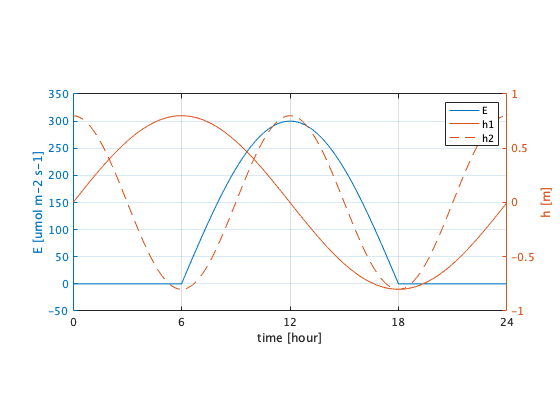

%Graph
fig = figure;
ax = gca;

pbaspect([2,1,1]);
grid on;

yyaxis left
plot(hour,E)
xlim([0 24])
ylim([-50 350])
xticks([0 6 12 18 24])
xlabel('time [hour]')
ylabel('E [umol m-2 s-1]')

yyaxis right
plot(hour,h1)
hold on;
plot(hour,h2)
ylim([-1 1])
ylabel('h [m]')

legend({'E','h1','h2'})

### 海水の水ポテンシャル$\Psi^{\textrm{SW}}$


$$\Psi =\Psi_p +\Psi_{\pi } +\Psi_m +\Psi_g$$


$\Psi_p$：圧力ポテンシャル（0から負値）

$\Psi_{\pi }$：浸透ポテンシャル（細胞だと正値（海水は負値（？））、Van't-Hoff eqn.$\Psi_{\pi } =\left(\frac{n}{V}\right)\textrm{iRT}$に従う）

$\Psi_m$：マトリックスポテンシャル（0から負値）

$\Psi_g$：重力ポテンシャル（0から正値、$\Psi_g =\rho \textrm{gh}$、

ex: 高さ10mの葉なら1000kg m-3 * 10m s-2 * 10m = 100000Pa = 0.1MPa）

（出典：https://www.ecology.kyoto-u.ac.jp/~atto/PDF/EcoI_04_Ishida.pdf、高さ10mの葉に計算ミス有）

S_ex = 40       %(psu)

S_ex = 40

塩分S(psu)の海水を考える。（psuは‰と同義とする。）

海水中に含まれる塩の平均モル質量M[g/mol]は、質量%濃度：NaCl: 77.9%, MgCl2: 9.6%, MgSO4: 6.1%, CaSO4: 4.0%, KCl: 2.1%とすると

M = 58.4*0.779 + 95.2*0.096 + 120.4*0.061 + 136.1*0.04 + 74.6*0.021    %[g/mol]

M = 68.9878

海水1000g中に塩S[g]のとき、

塩の物質量S/M[mol]、

体積1000[g]/(997+S)[g/L]=1000/(997+S)*10^-3[m3]

モル濃度Cは

rho_ex = 997 + S_ex;                      %[kg m-3]=[g L-1]
C_ex = S_ex/M / ((1000/rho_ex)*10^(-3))   %[mol/m3]

C_ex = 601.2657

（普通の海水(35psu)なら500mM=500mol/m3だから妥当）

% rho = 997 + S;                     %[kg m-3]=[g L-1]
% C = S /M / ((1000/rho)*10^(-3));   %[mol/m3]

#### 海水の浸透ポテンシャル$\Psi_{\pi }^{\textrm{SW}} \left(S\right)$


$$\Psi_{\pi }^{\textrm{SW}} \left(S\right)=\frac{n}{V\left(S\right)}\textrm{iRT}=C\left(S\right)\textrm{iRT}$$


ファントホッフ係数iをおよそ1.9とすると、（NaClで1+電離度0.925位、他物質は電離度低い）

i_vanthoff = 1.9; %Van't Hoff Coefficient
R = 8.31446;     %[J K-1 mol-1]
T_ex = 300;       %[K] (27 degC)
psi_sw_pi_ex = -C_ex * i_vanthoff * R * 300  %[Pa]

psi_sw_pi_ex = -2.8495e+06

となり、Touchette (2007)の40psuの時3.2MPaとおよそ等しい値を取る。（10psuで-0.8MPa、40psuで-3.2MPaと、単純に4倍になっているので、水深による圧ポテンシャルは考慮していないと思われる。）

#### 海水の圧ポテンシャル$\Psi_P^{\textrm{SW}} \left(d\right)$

P_air = 101325;  %[Pa]
g = 9.80665;    %[m s-2]
d_ex = 0.5       %[m]

d_ex = 0.5000

psi_sw_p_ex_absolute = -P_air -rho_ex * g * d_ex;  %[Pa] (absolute)（絶対圧は考えない？）
psi_sw_p_ex = -rho_ex * g * d_ex          %[Pa] (gauge)

psi_sw_p_ex = -5.0847e+03

#### よって、$\Psi^{\textrm{SW}} =\Psi_{\pi }^{\textrm{SW}} \left(S\right)+\Psi_P^{\textrm{SW}} \left(d\right)$

psi_sw_ex = psi_sw_pi_ex + psi_sw_p_ex  %[Pa]

psi_sw_ex = -2.8546e+06

% psi_sw_pi = -C * i_vanthoff * R * T;  %[Pa]
% % psi_sw_p = -rho * g * d;  %[Pa]
% % psi_sw = psi_sw_pi + psi_sw_p;  %[Pa]

### 大気の水ポテンシャル$\Psi^{\textrm{air}} \cong \Psi_{\pi }^{\textrm{air}} \left(\textrm{RH}\right)$

RH = 0.5                       %Relative Humidity

RH = 0.5000

Vm = 18 * 10^(-6);                     %[m3 mol-1] Partial molar volume of water
psi_air = R * T_ex * log(RH) / Vm      %[Pa]

psi_air = -9.6052e+07

### 土壌の水ポテンシャル$\Psi^{\textrm{soil}}$

#### 土壌の浸透ポテンシャル$\Psi_{\pi }^{\textrm{soil}}$


$$\Psi_{\pi }^{\textrm{soil}} =-\textrm{nCRT}$$
